## The Debugging Game

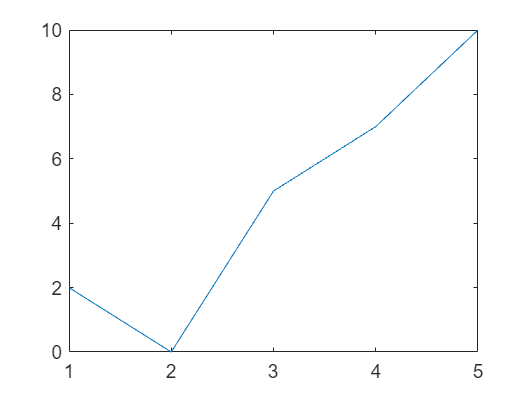

are_you = input('Ready? Set? ','s');

*Hints*: go over how to generate random integers in particular ranges and how to create an array of random integers; remember that subplots are numbered rowwise, and examine the use of the r & c variables.

%% This program presents the user with a matrix of random integers and plots
%% the numbers of each row into an organized subplot

fprintf(['\nAlright, let''s %s Now debug this...\nGenerate a 6x5 matrix of ' ...
    'random integers from 0 to 10 then plot \nthe values of each row as blue ' ...


Alright, let's o Now debug this...
Generate a 6x5 matrix of random integers from 0 to 10 then plot 
the values of each row as blue stars in a 2x3 subplot!

    'stars in a 2x3 subplot!'], are_you)

%% Initialize the 6 x 5 matrix of random integers ranging from 0 to 10
%% DO NOT suppress the matrix generated. We want to see the values.
% Change "randi([6,5], 10) to "randi([0,10], 6, 5]."
% When we generate the random integer, it's "randi([imin, imax], matrix)"
plot_mat = randi([0,10], 6, 5)

plot_mat =      3     7     2     3     9
     6     9     9     2     6
     2    10     2     2     6
     8     6     8     6    10
     2     1     2     5     3
     5     1    10     3     8


%% Find the size of the matrix
[r, c] = size(plot_mat);

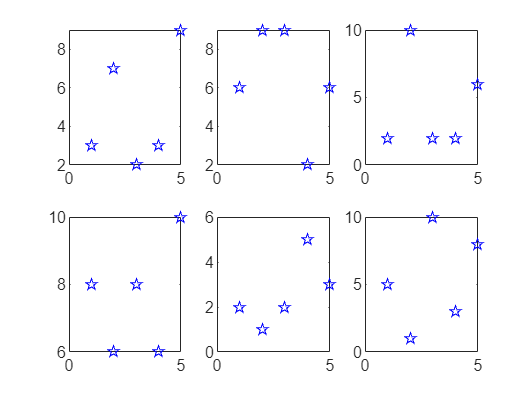

%% Use a for loop to create the subplot!
for i = 1:r
    subplot(2,3,i)      % we want 2 rows of plot
    plot(plot_mat(i,:), 'bp')
end